# Compare Density and Rate models - corrected

corrected in 2 ways:

1) Use same nests in the timeframe 0-135 days, so number of nests change constant

2) don't use nest F24, as it barely increases in area throughout this timeframe

Use Nests: 3,4,5,6,8,11,12,13,15,16,17,18,20,22,25,26,27,28,29

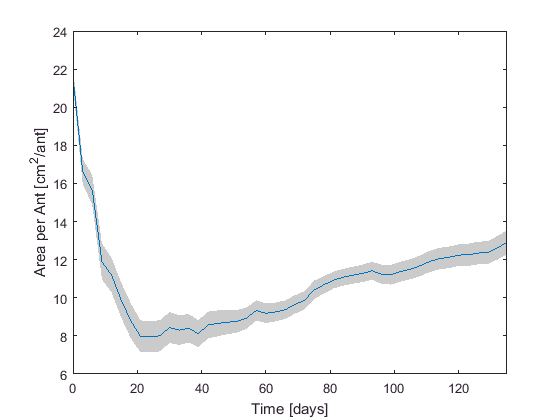

load('Data\MeanData\MeanBinnedData.mat','S','M','t','varNames')
UseNests = [3:6,8,11:13,15:18,20,22,25:29];
t0 = find(t==0); tend = find(t==135);
t1 = t(t0:tend);

A = mean(M(11).BinMat(t0:tend,UseNests),2);
Asd = std(M(11).BinMat(t0:tend,UseNests),0,2);
Aer = Asd./sqrt(length(UseNests)); % error as SEM

N = mean(M(13).BinMat(t0:tend,UseNests),2);
Nsd = std(M(13).BinMat(t0:tend,UseNests),0,2);
Ner = Nsd./sqrt(length(UseNests)); % error as SEM

% calc new error for ApA
a_er = sqrt((Asd./A).^2 + (Nsd./N).^2);

% rates
dAdt = diff(A)./3;
dNdt = diff(N)./3;

% choose ast
a = A./N;
figure;
er1 = a - a_er;
er2 = a + a_er;
f2 = fill([t1;flip(t1)],[er1;flip(er2)],'k','LineStyle','none');
alpha(f2,0.2)
hold on
plot(t1,a,'-')
ylabel('Area per Ant [cm^2/ant]')
xlabel('Time [days]')
xlim([0 135])

Mean_aST = mean(a(end-10:end)) % mean of last month

Mean_aST = 12.1841

choose ast = 12.2 for mean data

## Find 'r' , optimal rate parameter for density model

dA1_func = @(A,N,ast,r) N.*r.*(1-(A./N)./ast);
R = 0.5:0.001:1.5;
RMSE_dA = zeros(numel(R)-1,1);
RMSE_A = zeros(numel(R),1);

for j=1:numel(R)
    Am1 = zeros(numel(A),1);
    dA1 = zeros(numel(A)-1,1);
    Am1(1)=A(1);
    for i=2:numel(A)
        dA1(i-1) = dA1_func(A(i-1),N(i-1),12.2,R(j));
        if dA1(i-1)<0
            dA1(i-1)=0;
        end
        Am1(i) = Am1(i-1)+3.*dA1(i-1);
    end
    RMSE_dA(j) = sqrt(immse(dAdt,dA1));
    RMSE_A(j) = sqrt(immse(A,Am1));
end

[Min,I] = min(RMSE_dA)

Min = 0.4132

I = 304

disp('optimal r value dAdt')

optimal r value dAdt


R(I)

ans = 0.8030

[Min,I] = min(RMSE_A)

Min = 5.5543

I = 356

disp('optimal r value A')

optimal r value A


R(I)

ans = 0.8550

## Compare models on mean data

% density model
AST = 12.2;
Rr = R(I);
Am1 = zeros(numel(A),1);
dA1 = zeros(numel(A)-1,1);
Am1(1)=A(1);
for i=2:numel(A)
    dA1(i-1) = dA1_func(A(i-1),N(i-1),AST,Rr);
    if dA1(i-1)<0
       dA1(i-1)=0;
    end
    Am1(i) = Am1(i-1)+3.*dA1(i-1);
end
% Rate model
[dA2,Am2] = dAdtModel2(-48,0,2.039,0,dNdt,A(1));


figure
subplot(1,2,1)
plot(t1(1:end-1),dAdt,'-s',t1(1:end-1),dA1,t1(1:end-1),dA2,'LineWidth',2)
xlabel('time [days]')
ylabel('digging rate [cm^2/day]')
legend({'Mean Total Area','Density model','Rate model'},'Location','northwest')
RMSE1 = sqrt(immse(dAdt,dA1))

RMSE1 = 0.4190

RMSE2 = sqrt(immse(dAdt,dA2))

RMSE2 = 0.3158



f = subplot(1,2,2)

f =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.5703 0.1100 0.3326 0.8150]
            Units: 'normalized'

  Show all properties


c = colormap(lines);

set(f,'defaultAxesColorOrder',[c(1,:);0 0 0]);
    hold on
    yyaxis left
    er1 = A - Aer;
    er2 = A + Aer;
    f2 = fill([t1;flip(t1)],[er1;flip(er2)],'k','LineStyle','none');
    alpha(f2,0.2)
    plot(t1,A,'-s','Color',c(1,:),'LineWidth',2)
    plot(t1,Am1,'-','Color',c(2,:),'LineWidth',2)
    plot(t1,Am2,'-','Color',c(3,:),'LineWidth',2)
    
    yyaxis right
    plot(t1,N,'--k','LineWidth',2)
    ylabel('no. ants')
    
xlabel('time [days]')
ylabel('area [cm^2]')
RMSE1 = sqrt(immse(A,Am1))

RMSE1 = 5.5543

RMSE2 = sqrt(immse(A,Am2))

RMSE2 = 6.5922

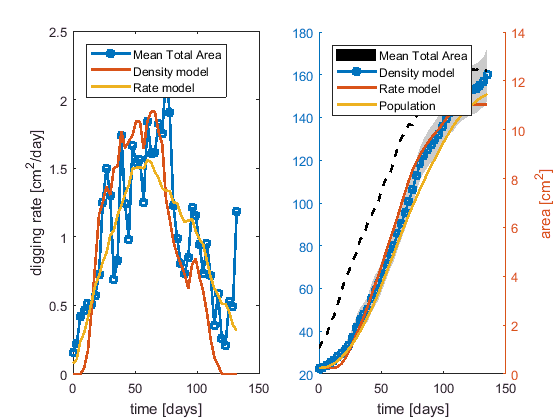


legend({'Mean Total Area','Density model','Rate model','Population',},'Location','northwest')

## Check for 3 experiments: F3, F4 and F25

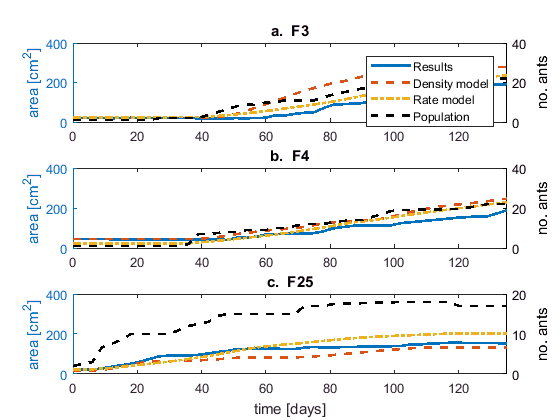

   82.8732


   23.8653


   36.8679


   28.3156


   28.8801


   33.2284


fig = figure;

set(fig,'defaultAxesColorOrder',[c(1,:);0 0 0]);
j=0;
letter = {'a','b','c'};
for k=[3 4 25]
    j=j+1;
    A_n = S(k).B{t0:tend,11};
    N_n = S(k).B{t0:tend,13};
    % rates
    dAdt = diff(A_n)./3;
    dNdt = diff(N_n)./3;
    
    % density model
    Am1 = zeros(numel(A_n),1);
    Am1(1)=A_n(1);
    for i=2:numel(A_n)
        dA1 = dA1_func(A_n(i-1),N_n(i-1),8.5,Rr);
        if dA1<0
            dA1=0;
        end
        Am1(i) = Am1(i-1)+3.*dA1;
    end
    % Rate model
    [dA2,Am2] = dAdtModel2(-48,0,2.039,0,dNdt,A(1));
    
    subplot(3,1,j)
    % plot  pop curve
    yyaxis right
    plot(t1,N_n,'--k','LineWidth',2)
    ylabel('no. ants')
    hold on
    yyaxis left
    plot(t1,A_n,'LineStyle','-','Color',c(1,:),'LineWidth',2)
    plot(t1,Am1,'LineStyle','--','Color',c(2,:),'LineWidth',2)
    plot(t1,Am2,'LineStyle','-.','Color',c(3,:),'LineWidth',2)
    xlim([0 135])
    if j==1
        legend({'Results','Density model','Rate model','Population'})
    elseif j==3
        xlabel('time [days]')
    end
    ylabel('area [cm^2]')
    
    titles = strcat(letter(j),'.  F',num2str(k));
    title(titles)
  
    RMSE1 = sqrt(immse(A_n,Am1));
    disp(RMSE1)
    RMSE2 = sqrt(immse(A_n,Am2));
    disp(RMSE2)
end